# 2-3

clc
clear

## audioread() function is used to import audio file as array.


[x_t, fs] = audioread('Audio01.wav');
x_t = x_t';
t_axis = linspace(0, length(x_t) / fs, length(x_t));


## Next we transfer the imported audio to the Fourier domain.

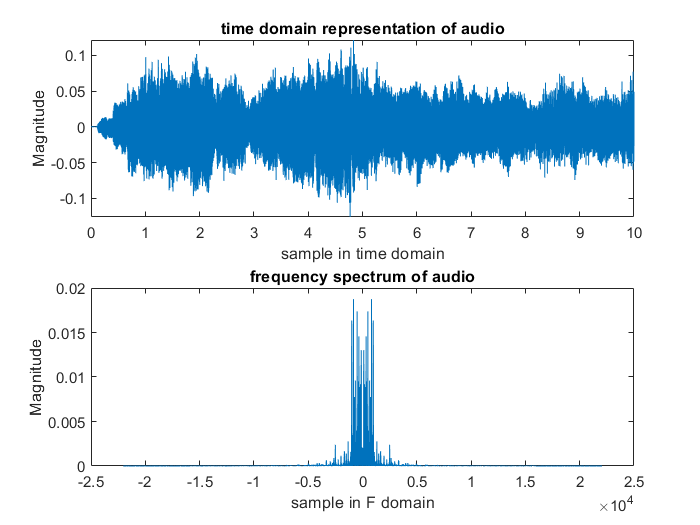

N = length(x_t);
f_axis = linspace(-fs / 2, fs / 2, N);
FT_x = fftshift(fft(x_t))/fs;

figure;
subplot(2,1,1);
plot(t_axis,x_t);
xlabel('sample in time domain');
ylabel('Magnitude');
title('time domain representation of audio');
subplot(2,1,2);
plot(f_axis, abs(FT_x) );
xlabel('sample in F domain');
ylabel('Magnitude');
title('frequency spectrum of audio');

## Now we design a low pass filter using filterdesigner and import it using load() function and next we pass the audio signal through the designed filter.

load('Filter1.mat');
lowpass_x_t = filter(Num,1,x_t);


## Fourier transform of low_pass_x_t and illustration.

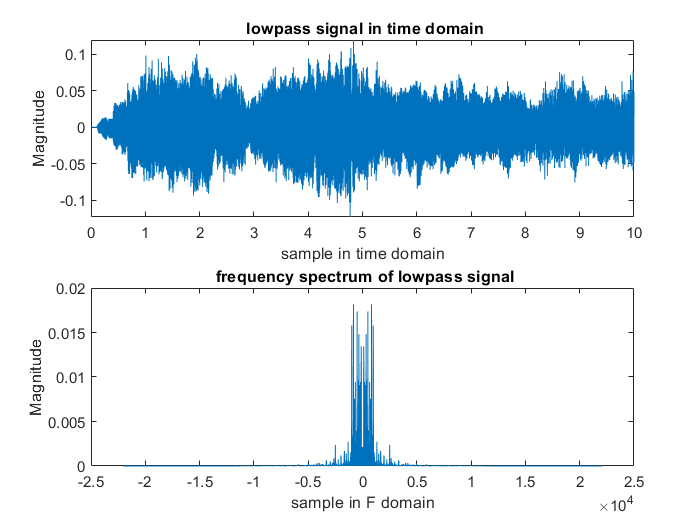

N_lowpass_x_t = length(lowpass_x_t);
f_axis_lowpass_x_t = linspace(-fs / 2, fs / 2, N_lowpass_x_t);
FT_lowpass_x_t = fftshift(fft(lowpass_x_t))/fs;
t_axis_lowpass_x_t = linspace(0, length(lowpass_x_t) / fs, length(lowpass_x_t));
figure;
subplot(2,1,1);
plot(t_axis_lowpass_x_t,lowpass_x_t);
xlabel('sample in time domain');
ylabel('Magnitude');
title(' lowpass signal in time domain');
subplot(2,1,2);
plot(f_axis_lowpass_x_t, abs(FT_lowpass_x_t) );
xlabel('sample in F domain');
ylabel('Magnitude');
title(' frequency spectrum of lowpass signal');

## Multiplication of low_pass_x_t by carrier


%lowpass signal multiplied by carrier=lsmc
n=0:length(lowpass_x_t)-1;
f0=10000;
sn=2*cos(2*pi*f0/fs  .*n);
lsmc=lowpass_x_t .* sn;


## Next we want to illustrate low_pass_x_t multiplied by carrier in Fourier domain

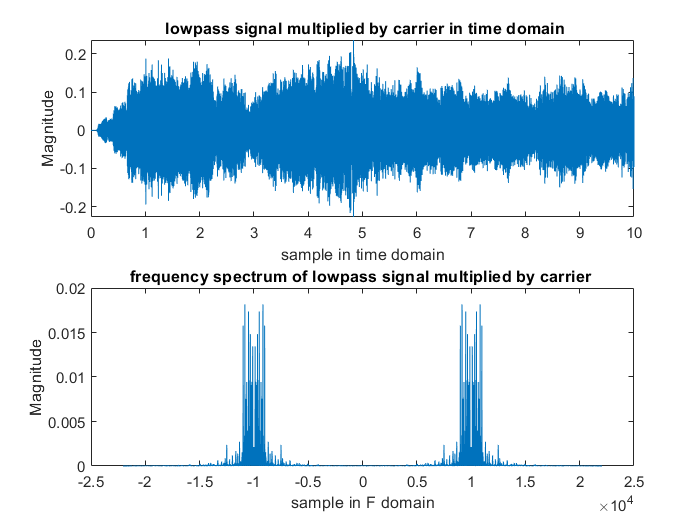

N_lsmc = length(lsmc);
f_axis_lsmc = linspace(-fs / 2, fs / 2, N_lsmc); %defining f axis
FT_lsmc = fftshift(fft(lsmc))/fs;
t_axis_lsmc = linspace(0, length(lsmc) / fs, length(lsmc));

figure;
subplot(2,1,1);
plot(t_axis_lsmc,lsmc);
xlabel('sample in time domain');
ylabel('Magnitude');
title(' lowpass signal multiplied by carrier in time domain');
subplot(2,1,2);
plot(f_axis_lsmc, abs(FT_lsmc) );
xlabel('sample in F domain');
ylabel('Magnitude');
title('frequency spectrum of lowpass signal multiplied by carrier ');

## Now we want to pass the los_pass_x_t multiplied by the carier through the filter which was designed previously.

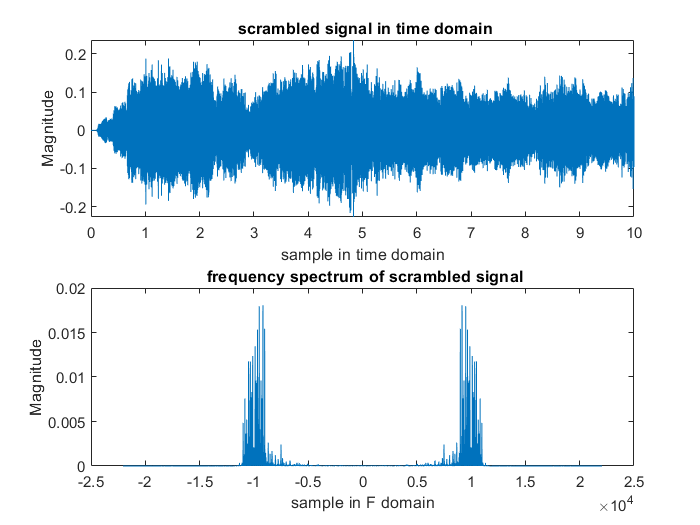

filtered_lsmc = filter(Num,1,lsmc);

N_filtered_lsmc = length(filtered_lsmc);
f_axis_filtered_lsmc = linspace(-fs / 2, fs / 2, N_filtered_lsmc);
FT_filtered_lsmc = fftshift(fft(filtered_lsmc))/fs;
t_axis_filtered_lsmc = linspace(0, length(filtered_lsmc) / fs, length(filtered_lsmc));
figure;
subplot(2,1,1);
plot(t_axis_filtered_lsmc,lsmc);
xlabel('sample in time domain');
ylabel('Magnitude');
title(' scrambled signal in time domain');
subplot(2,1,2);
plot(f_axis_filtered_lsmc, abs(FT_filtered_lsmc) );
xlabel('sample in F domain');
ylabel('Magnitude');
title(' frequency spectrum of scrambled signal');

## Generating scrambled signal which

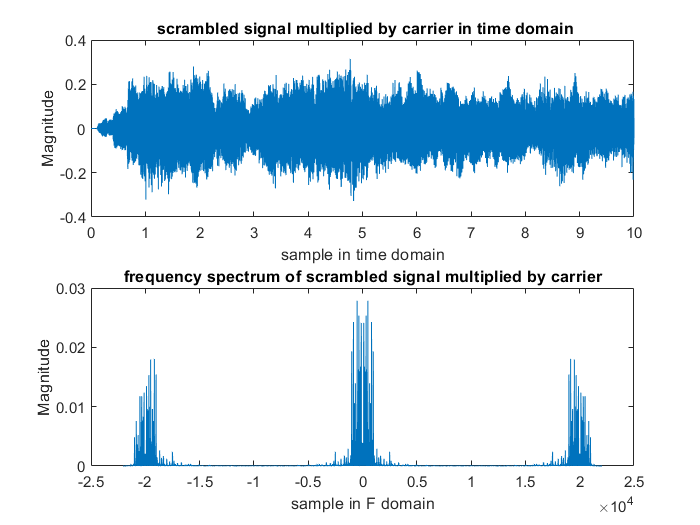

%scrambled signal multiplied by carrier=ssmc
n2=0:length(filtered_lsmc)-1;
f0=10000;
sn2=2*cos(2*pi*f0/fs  .*n2);
ssmc=filtered_lsmc .* sn2;


% Fourier transform of scrambled audio after multiplication by carrier
N_ssmc = length(ssmc);
f_axis_ssmc = linspace(-fs / 2, fs / 2, N_ssmc);
FT_ssmc = fftshift(fft(ssmc))/fs;
t_axis_ssmc = linspace(0, length(ssmc) / fs, length(ssmc));


%illustration
figure;
subplot(2,1,1);
plot(t_axis_ssmc,ssmc);
xlabel('sample in time domain');
ylabel('Magnitude');
title(' scrambled signal multiplied by carrier in time domain');
subplot(2,1,2);
plot(f_axis_ssmc , abs(FT_ssmc) );
xlabel('sample in F domain');
ylabel('Magnitude');
title('frequency spectrum of scrambled signal multiplied by carrier');

## Now we pass the "scrambled signal multiplied by carrier" through the designed filter

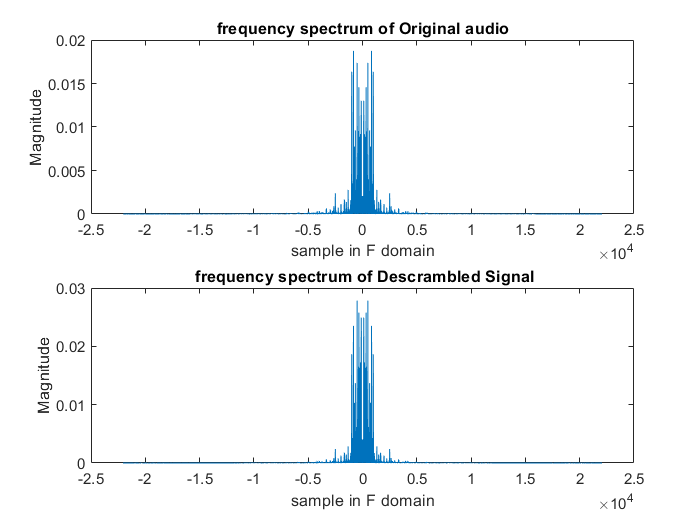

filtered_ssmc=filter(Num,1,ssmc);

N_filtered_ssmc = length(filtered_ssmc);
f_axis_filtered_ssmc = linspace(-fs / 2, fs / 2, N_filtered_ssmc);
FT_filtered_ssmc = fftshift(fft(filtered_ssmc))/fs;
t_axis_filtered_ssmc = linspace(0, length(filtered_ssmc) / fs, length(filtered_ssmc));
figure;
subplot(2,1,1);
plot(t_axis_filtered_ssmc,ssmc);
xlabel('sample in time domain');
ylabel('Magnitude');
title(' Descrambled Signal in time domain');
subplot(2,1,2);
plot(f_axis_filtered_ssmc, abs(FT_filtered_ssmc) );
xlabel('sample in F domain');
ylabel('Magnitude');
title(' frequency spectrum of Descrambled Signal');



% Descrambled Signal vs Original Signal
subplot(2,1,1);
plot(f_axis, abs(FT_x) );
xlabel('sample in F domain');
ylabel('Magnitude');
title('frequency spectrum of Original audio');
subplot(2,1,2);
plot(f_axis_filtered_ssmc, abs(FT_filtered_ssmc) );
xlabel('sample in F domain');
ylabel('Magnitude');
title(' frequency spectrum of Descrambled Signal');

## Using audiowrite to see how the scrambled audio is...

audiowrite('Scrambled audio.wav', ssmc, fs);
audiowrite('Scrambled audio after filter.wav', filtered_ssmc, fs);

